# First Order Ordinary Linear Systems : Sketch and Solve

% Sloution Benchmark
u  = @(x) [sin(x) ;  cos(x)] ;
Du = @(x) [cos(x) ; -sin(x)] ; 

% System Settings
m  = 2 ;  % number of dependent variables
A1 = @(x) [cos(x), -sin(x); sin(x), cos(x)];
A0 = @(x) [cos(x), -sin(x); sin(x), cos(x)];
f  = @(x) [1 ; 1]  ;
g  = @(x) sin(x) +  cos(x)     ; % u(x)
Omega = [ 0 , pi ] ;                 % Omega = [ a , b ] domain

% Construct the model
sample = cell(1,6);
h = [0.004, 0.005, 0.01, 0.05, 0.1, 0.5];
num_sample = length(h);
k = ceil(1./(pi*h))  % k*n interior points for n basis, the system is approximately k*n*m by m*n

k =     80    64    32     7     4     1


k = arrayfun(@(x)max([x,10]),k);
lambda = h.^(-1/2); %100 * ones(1,num_sample);       % square(weights) for BC
skt_coe = 2.8 ; % sketch skt_coe * (N+1) rows

rng(42) ;  % random seed
for i = 1:num_sample
    fprintf("Sample %d starts : ", i)

    % Construction
    model = Collocation1D(m, Omega) ;
    model.fitInterior(A1,A0,f,2)
    model.fitBoundary([],@(x) [1,1],g,1); %model.fitBoundary([],[],g)
    model.fitTrueSol(u, Du)
    
    % Discretization
    n = round(pi/h(i)) + 1 ;
    model.linear_discretize(n) ;

    % Points selectionb
    sample{i}.k = k(i) ;
    sample{i}.interior_points = linspace(Omega(1), Omega(2), k(i)*n) ; % interior points
    sample{i}.boundary_points = Omega ;                                % boundary points

    % System assemble
    sample{i}.lambda = lambda(i) ;  
    Lambda = diag(lambda(i)*ones(1,1)) ; 

    [B_Omega, d_Omega, ~] = model.Assemble_B_Omega(sample{i}.interior_points) ;
    [B_Gamma, d_Gamma, ~] = model.Assemble_B_Gamma(sample{i}.boundary_points, Lambda) ;
    
    B = [B_Omega ; B_Gamma] ;
    d = [d_Omega ; d_Gamma] ;

    sample{i}.B = B ; 
    sample{i}.d = d ;

    % System solving without sketching
    c = B\d ; 
    sample{i}.c_full = c ; 
    sample{i}.res_full = norm(B*c-d) ;

    model.C = model.reshape2mat(c) ;
    sample{i}.model = model ;

    % Sketching
    [M, N] = size(sample{i}.B) ;
    S = randn(round(skt_coe*(N+1)), M) ; %% 
    SB = S * B ; Sd = S * d ;

    sample{i}.S = S ;
    sample{i}.SB = SB ; 
    sample{i}.Sd = Sd ;
     
    c_skt = SB \ Sd ; 
    sample{i}.c_skt = c_skt ;
    sample{i}.res_skt = norm(B*c_skt-d) ;

    fprintf("finished")
end

Sample 1 starts : 

finished

Sample 2 starts : 

finished

Sample 3 starts : 

finished

Sample 4 starts : 

finished

Sample 5 starts : 

finished

Sample 6 starts : 

finished

% Error Calculation
data.h = [] ;
data.min_sigB = [] ;
data.L2Error_wo_skt = [] ;
data.L2Error_wt_skt = [] ;

data.resi_full = [] ;
data.resi_skt  = [] ;
data.coe_error = [] ;
data.k_GQ = ((sqrt(skt_coe)+1)/(sqrt(skt_coe)-1)) * ones(1,num_sample) ;

for i = 1:num_sample
   
    model = sample{i}.model ;
    C_skt = model.reshape2mat(sample{i}.c_skt) ;

    abs_error_1 = @(x) abs(model.u(x) - model.evaluate_LSFEM_elewise(x)) ;
    abs_error_2 = @(x) abs(model.u(x) - model.evaluate_LSFEM_elewise(x,C_skt)) ;
    
    L2_1 = sqrt(integral(@(x) abs_error_1(x).^2, Omega(1), Omega(2), 'ArrayValued', true, 'AbsTol', 1e-12)) ;
    L2_2 = sqrt(integral(@(x) abs_error_2(x).^2, Omega(1), Omega(2), 'ArrayValued', true, 'AbsTol', 1e-12)) ;
    
    data.L2Error_wo_skt = [data.L2Error_wo_skt, L2_1] ;
    data.L2Error_wt_skt = [data.L2Error_wt_skt, L2_2] ;
    data.h = [data.h, sample{i}.model.gm.Mesh.MaxElementSize] ;

    data.resi_full = [data.resi_full, sample{i}.res_full] ;
    data.resi_skt  = [data.resi_skt, sample{i}.res_skt] ;
    data.coe_error = [data.coe_error, norm(sample{i}.c_full-sample{i}.c_skt)] ;
    data.min_sigB  = [data.min_sigB, svds(sample{i}.B, 1, 'smallest')] ;

end   


% save('./data/1D_SketchAndSolve_CollocationExample_01.mat', 'data');

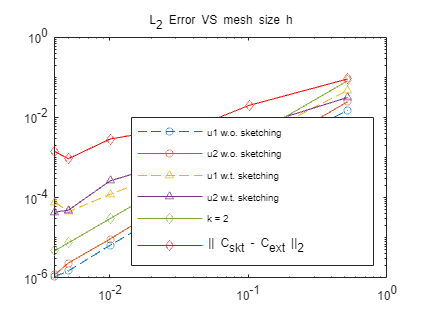

% Plot the error
load('./data/1D_SketchAndSolve_CollocationExample_01.mat');
h = data.h ; 

loglog(h, data.L2Error_wo_skt(1,:), '--o', ...
       h, data.L2Error_wo_skt(2,:), '-o' , ...
       h, data.L2Error_wt_skt(1,:), '--^' , ...
       h, data.L2Error_wt_skt(2,:), '-^' , ...
       h, 0.3*h.^2, '-diamond', ...
       h, (data.L2Error_wo_skt(1,:)+data.coe_error), 'r-diamond') ;

legend("u1 w.o. sketching", ...
       "u2 w.o. sketching", ...
       "u1 w.t. sketching", ...
       "u2 w.t. sketching", ...
       "k = 2", ...
       '|| C_skt - C_ext ||_2', ...
       'Location', 'southeast') ;

title('L_2 Error VS mesh size h');



% Plot the sketching error
loglog(h, data.resi_skt, '--o', ...
       h, data.resi_full, '-o', ...
       h, data.k_GQ.*data.resi_full, '-*') ;

legend("sketching res", ...
       "full res", ...
       "predicted upper bound", ...
       'Location', 'northwest') ;

title('Discrete Residual VS mesh size h');



loglog(h, data.coe_error, '--o', ...
       h, (1+data.k_GQ).*data.resi_full./data.min_sigB, '-*',...
       h, 1*h.^1, '-diamond') ;

legend("sketching coe error", ...
       "predicted upper bound", ...
       "k = 1", ...
       'Location', 'northwest') ;

title('Discrete coefficient error VS mesh size h');

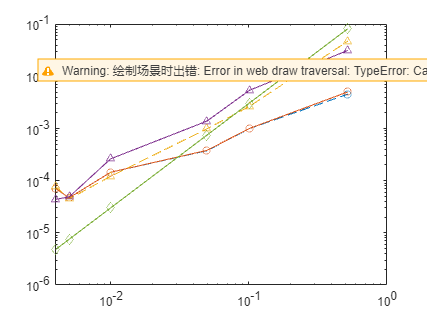

loglog(h, (data.L2Error_wo_skt(1,:)+data.coe_error)/20, '--o', ...
       h, (data.L2Error_wo_skt(2,:)+data.coe_error)/20, '-o' , ...
       h, data.L2Error_wt_skt(1,:), '--^' , ...
       h, data.L2Error_wt_skt(2,:), '-^' , ...
       h, 0.3*h.^2, '-diamond') ;

legend("u1 skt error bound", ...
       "u2 skt error bound", ...
       "u1 w.t. sketching", ...
       "u2 w.t. sketching", ...
       "k = 1", ...
       'Location', 'northwest') ;